# Data Analysis

Clear the workspace

close all;
clear;
clc;

Add paths

addpath run_01/ run_02/ run_03/ run_04/

Pose data

filename = "run_01-current_pose.csv";
r1_pose_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×12 table
                 time                 x_header_seq    x_header_stamp_secs    x_header_stamp_nsecs    x_header_frame_id    x_pose_position_x    x_pose_position_y    x_pose_position_z    x_pose_orientation_x    x_pose_orientation_y    x_pose_orientation_z    x_pose_orientation_w
    ______________________________    ____________    ___________________    ____________________    _________________    _________________    _________________    _________________    ____________________    ____________________    ____________________    ____________________

    {'2024/05/14/1

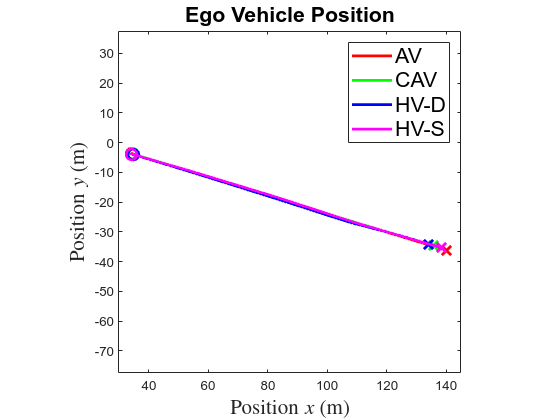

filename = "run_02-current_pose.csv";
r2_pose_data = readmatrix(filename);
filename = "run_03-current_pose.csv";
r3_pose_data = readmatrix(filename);
filename = "run_04-current_pose.csv";
r4_pose_data = readmatrix(filename);

figure(1)
plot(r1_pose_data(:, 6), r1_pose_data(:, 7), 'r', 'LineWidth', 2);
hold on
plot(r1_pose_data(1, 6), r1_pose_data(1, 7), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
plot(r1_pose_data(end, 6), r1_pose_data(end, 7), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
plot(r2_pose_data(:, 6), r2_pose_data(:, 7), 'g', 'LineWidth', 2);
plot(r2_pose_data(1, 6), r2_pose_data(1, 7), 'go', 'MarkerSize', 8, 'LineWidth', 2);
plot(r2_pose_data(end, 6), r2_pose_data(end, 7), 'gx', 'MarkerSize', 10, 'LineWidth', 2);
plot(r3_pose_data(:, 6), r3_pose_data(:, 7), 'b', 'LineWidth', 2);
plot(r3_pose_data(1, 6), r3_pose_data(1, 7), 'bo', 'MarkerSize', 8, 'LineWidth', 2);
plot(r3_pose_data(end, 6), r3_pose_data(end, 7), 'bx', 'MarkerSize', 10, 'LineWidth', 2);
plot(r4_pose_data(:, 6), r4_pose_data(:, 7), 'm', 'LineWidth', 2);
plot(r4_pose_data(1, 6), r4_pose_data(1, 7), 'mo', 'MarkerSize', 8, 'LineWidth', 2);
plot(r4_pose_data(end, 6), r4_pose_data(end, 7), 'mx', 'MarkerSize', 10, 'LineWidth', 2);
axis equal;
pbaspect([1 1 1]);
xlim([30 145]);
xlabel("Position $x$ (m)", "Interpreter", "latex", "FontSize", 16);
ylabel("Position $y$ (m)", "Interpreter", "latex", "FontSize", 16);
legend("AV", "", "", "CAV", "", "", "HV-D", "", "", "HV-S", "", "", "Location", "NE", "FontSize", 16);
title("Ego Vehicle Position", "FontSize", 16);
hold off

Twist data

filename = "run_01-current_velocity.csv";
r1_twist_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×11 table
                 time                 x_header_seq    x_header_stamp_secs    x_header_stamp_nsecs    x_header_frame_id    x_twist_linear_x    x_twist_linear_y    x_twist_linear_z    x_twist_angular_x    x_twist_angular_y    x_twist_angular_z
    ______________________________    ____________    ___________________    ____________________    _________________    ________________    ________________    ________________    _________________    _________________    _________________

    {'2024/05/14/15:11:17.573704'}       28665            1.7157e+09              5.7339e+08           {'base_link'}        

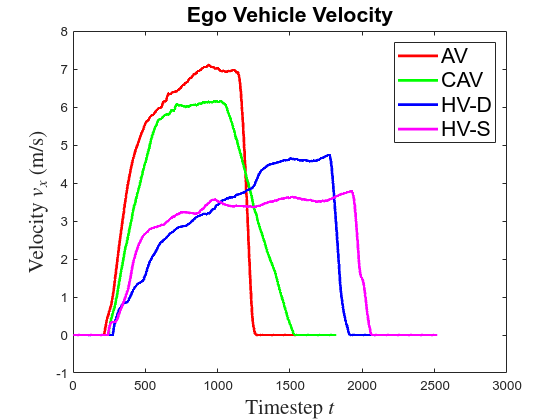

filename = "run_02-current_velocity.csv";
r2_twist_data = readmatrix(filename);
filename = "run_03-current_velocity.csv";
r3_twist_data = readmatrix(filename);
filename = "run_04-current_velocity.csv";
r4_twist_data = readmatrix(filename);

figure(2)
plot(r1_twist_data(:, 6), 'r', 'LineWidth', 2);
hold on
plot(r2_twist_data(:, 6), 'g', 'LineWidth', 2);
plot(r3_twist_data(:, 6), 'b', 'LineWidth', 2);
plot(r4_twist_data(:, 6), 'm', 'LineWidth', 2);
xlabel("Timestep $t$", "Interpreter", "latex", "FontSize", 16);
ylabel("Velocity $v_x$ (m/s)", "Interpreter", "latex", "FontSize", 16);
legend("AV", "CAV", "HV-D", "HV-S", "Location", "NE", "FontSize", 16);
title("Ego Vehicle Velocity", "FontSize", 16);
hold off

Throttle data

filename = "run_01-ssc-throttle_feedback.csv";
r1_throttle_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×6 table
                 time                 x_header_seq    x_header_stamp_secs    x_header_stamp_nsecs    x_header_frame_id    x_throttle_pedal
    ______________________________    ____________    ___________________    ____________________    _________________    ________________

    {'2024/05/14/15:11:17.458949'}       59059            1.7157e+09              4.5268e+08            {0×0 char}               0        
    {'2024/05/14/15:11:17.462981'}       59060            1.7157e+09              4.6267e+08            {0×0 char}               0        
    {'2024/05/14/15:11:17.473096'}       59061            1.7157e+09              4.7272e+08            {0×0 char}               0        
    {'2024/05/14/15:11:17.483100'}       59062            1.7157e+09              4.

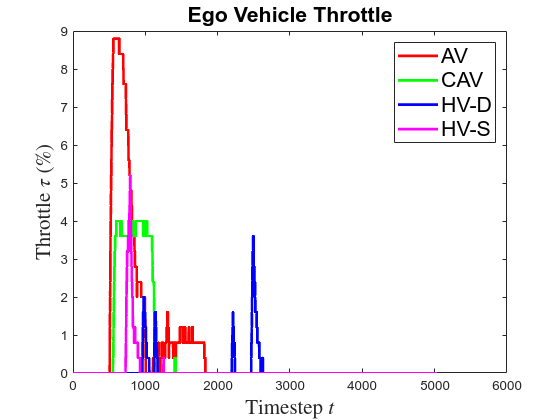

filename = "run_02-ssc-throttle_feedback.csv";
r2_throttle_data = readmatrix(filename);
filename = "run_03-ssc-throttle_feedback.csv";
r3_throttle_data = readmatrix(filename);
filename = "run_04-ssc-throttle_feedback.csv";
r4_throttle_data = readmatrix(filename);

figure(3)
plot(r1_throttle_data(:, 6).*100, 'r', 'LineWidth', 2);
hold on
plot(r2_throttle_data(:, 6).*100, 'g', 'LineWidth', 2);
plot(r3_throttle_data(:, 6).*100, 'b', 'LineWidth', 2);
plot(r4_throttle_data(:, 6).*100, 'm', 'LineWidth', 2);
xlabel("Timestep $t$", "Interpreter", "latex", "FontSize", 16);
ylabel("Throttle $\tau$ (\%)", "Interpreter", "latex", "FontSize", 16);
legend("AV", "CAV", "HV-D", "HV-S", "Location", "NE", "FontSize", 16);
title("Ego Vehicle Throttle", "FontSize", 16);
hold off

Steering data

filename = "run_01-ssc-steering_feedback.csv";
r1_steering_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×6 table
                 time                 x_header_seq    x_header_stamp_secs    x_header_stamp_nsecs    x_header_frame_id    x_steering_wheel_angle
    ______________________________    ____________    ___________________    ____________________    _________________    ______________________

    {'2024/05/14/15:11:17.794596'}       59093            1.7157e+09              7.9422e+08            {0×0 char}              -0.054105       
    {'2024/05/14/15:11:17.804336'}       59094            1.7157e+09              8.0397e+08            {0×0 char}              -0.054105       
    {'2024/05/14/15:11:17.814493'}       59095            1.7157e+09              8.1422e+08            {0×0 char}              -0.054105       
    {'2024/05/14/15:11:17.826811'}       59096        

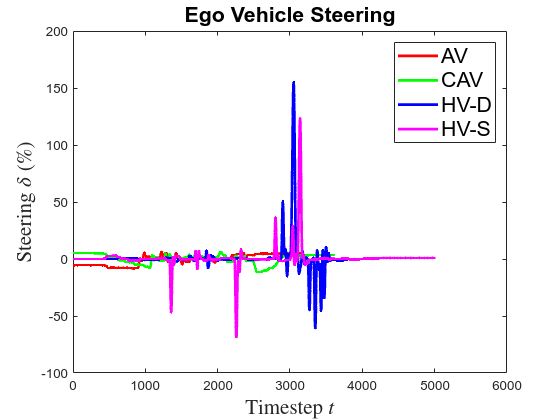

filename = "run_02-ssc-steering_feedback.csv";
r2_steering_data = readmatrix(filename);
filename = "run_03-ssc-steering_feedback.csv";
r3_steering_data = readmatrix(filename);
filename = "run_04-ssc-steering_feedback.csv";
r4_steering_data = readmatrix(filename);

figure(4)
plot(r1_steering_data(:, 6).*100, 'r', 'LineWidth', 2);
hold on
plot(r2_steering_data(:, 6).*100, 'g', 'LineWidth', 2);
plot(r3_steering_data(:, 6).*100, 'b', 'LineWidth', 2);
plot(r4_steering_data(:, 6).*100, 'm', 'LineWidth', 2);
xlabel("Timestep $t$", "Interpreter", "latex", "FontSize", 16);
ylabel("Steering $\delta$ (\%)", "Interpreter", "latex", "FontSize", 16);
legend("AV", "CAV", "HV-D", "HV-S", "Location", "NE", "FontSize", 16);
title("Ego Vehicle Steering", "FontSize", 16);
hold off

Brake data

filename = "run_01-ssc-brake_feedback.csv";
r1_brake_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×6 table
                 time                 x_header_seq    x_header_stamp_secs    x_header_stamp_nsecs    x_header_frame_id    x_brake_pedal
    ______________________________    ____________    ___________________    ____________________    _________________    _____________

    {'2024/05/14/15:11:17.583297'}       59071            1.7157e+09              5.8293e+08            {0×0 char}            0.256    
    {'2024/05/14/15:11:17.593321'}       59072            1.7157e+09              5.9299e+08            {0×0 char}            0.256    
    {'2024/05/14/15:11:17.603258'}       59073            1.7157e+09              6.0293e+08            {0×0 char}            0.256    
    {'2024/05/14/15:11:17.614893'}       59074            1.7157e+09              6.1295e+08       

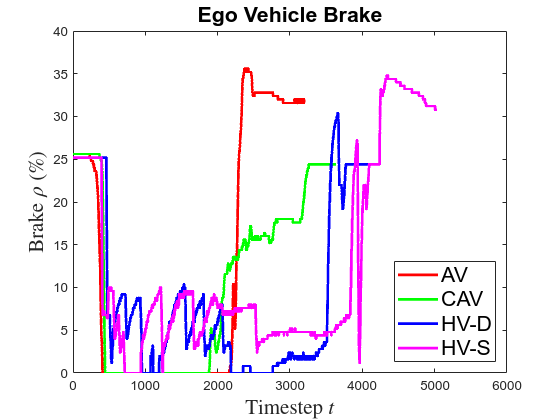

filename = "run_02-ssc-brake_feedback.csv";
r2_brake_data = readmatrix(filename);
filename = "run_03-ssc-brake_feedback.csv";
r3_brake_data = readmatrix(filename);
filename = "run_04-ssc-brake_feedback.csv";
r4_brake_data = readmatrix(filename);

figure(5)
plot(r1_brake_data(:, 6).*100, 'r', 'LineWidth', 2);
hold on
plot(r2_brake_data(:, 6).*100, 'g', 'LineWidth', 2);
plot(r3_brake_data(:, 6).*100, 'b', 'LineWidth', 2);
plot(r4_brake_data(:, 6).*100, 'm', 'LineWidth', 2);
xlabel("Timestep $t$", "Interpreter", "latex", "FontSize", 16);
ylabel("Brake $\rho$ (\%)", "Interpreter", "latex", "FontSize", 16);
legend("AV", "CAV", "HV-D", "HV-S", "Location", "SE", "FontSize", 16);
title("Ego Vehicle Brake", "FontSize", 16);
hold off

Combined plot

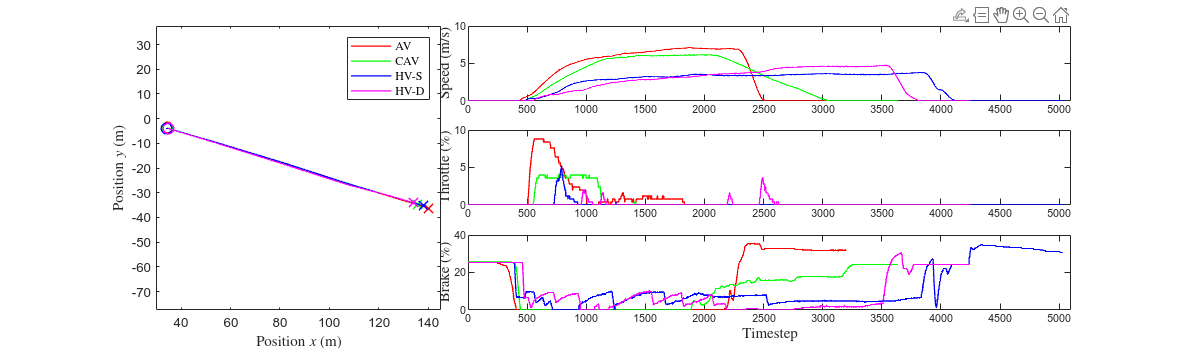

fig = figure(6);
fig.Position(3:4) = [1700, 500];
% Plot velocity
subplot(3,9,4:9)
plot(linspace(0,2*length(r1_twist_data(:, 6)),length(r1_twist_data(:, 6))), r1_twist_data(:, 6), 'r', 'LineWidth', 1);
hold on
plot(linspace(0,2*length(r2_twist_data(:, 6)),length(r2_twist_data(:, 6))), r2_twist_data(:, 6), 'g', 'LineWidth', 1);
plot(linspace(0,2*length(r4_twist_data(:, 6)),length(r4_twist_data(:, 6))), r4_twist_data(:, 6), 'b', 'LineWidth', 1);
plot(linspace(0,2*length(r3_twist_data(:, 6)),length(r3_twist_data(:, 6))), r3_twist_data(:, 6), 'm', 'LineWidth', 1);
% xlabel("Timestep", "Interpreter", "latex", "FontSize", 11);
ylabel("Speed (m/s)", "Interpreter", "latex", "FontSize", 11);
xlim([0 5100]);
ylim([0 10]);
hold off;
% Plot throttle
subplot(3,9,13:18)
plot(r1_throttle_data(:, 6).*100, 'r', 'LineWidth', 1);
hold on
plot(r2_throttle_data(:, 6).*100, 'g', 'LineWidth', 1);
plot(r4_throttle_data(:, 6).*100, 'b', 'LineWidth', 1);
plot(r3_throttle_data(:, 6).*100, 'm', 'LineWidth', 1);
% xlabel("Timestep", "Interpreter", "latex", "FontSize", 11);
ylabel("Throttle (\%)", "Interpreter", "latex", "FontSize", 11);
xlim([0 5100]);
ylim([0 10]);
hold off;
% Plot brake
subplot(3,9,22:27)
plot(r1_brake_data(:, 6).*100, 'r', 'LineWidth', 1);
hold on
plot(r2_brake_data(:, 6).*100, 'g', 'LineWidth', 1);
plot(r4_brake_data(:, 6).*100, 'b', 'LineWidth', 1);
plot(r3_brake_data(:, 6).*100, 'm', 'LineWidth', 1);
xlabel("Timestep", "Interpreter", "latex", "FontSize", 11);
ylabel("Brake (\%)", "Interpreter", "latex", "FontSize", 11);
xlim([0 5100]);
ylim([0 40]);
hold off;
% Plot position
subplot(3,9,[1,2,3,10,11,12,19,20,21])
plot(r1_pose_data(:, 6), r1_pose_data(:, 7), 'r', 'LineWidth', 1);
hold on
plot(r1_pose_data(1, 6), r1_pose_data(1, 7), 'ro', 'MarkerSize', 8, 'LineWidth', 1);
plot(r1_pose_data(end, 6), r1_pose_data(end, 7), 'rx', 'MarkerSize', 10, 'LineWidth', 1);
plot(r2_pose_data(:, 6), r2_pose_data(:, 7), 'g', 'LineWidth', 1);
plot(r2_pose_data(1, 6), r2_pose_data(1, 7), 'go', 'MarkerSize', 8, 'LineWidth', 1);
plot(r2_pose_data(end, 6), r2_pose_data(end, 7), 'gx', 'MarkerSize', 10, 'LineWidth', 1);
plot(r4_pose_data(:, 6), r4_pose_data(:, 7), 'b', 'LineWidth', 1);
plot(r4_pose_data(1, 6), r4_pose_data(1, 7), 'bo', 'MarkerSize', 8, 'LineWidth', 1);
plot(r4_pose_data(end, 6), r4_pose_data(end, 7), 'bx', 'MarkerSize', 10, 'LineWidth', 1);
plot(r3_pose_data(:, 6), r3_pose_data(:, 7), 'm', 'LineWidth', 1);
plot(r3_pose_data(1, 6), r3_pose_data(1, 7), 'mo', 'MarkerSize', 8, 'LineWidth', 1);
plot(r3_pose_data(end, 6), r3_pose_data(end, 7), 'mx', 'MarkerSize', 10, 'LineWidth', 1);
axis equal;
pbaspect([1 1 1]);
xlim([30 145]);
xlabel("Position $x$ (m)", "Interpreter", "latex", "FontSize", 11);
ylabel("Position $y$ (m)", "Interpreter", "latex", "FontSize", 11);
% Common title and legend
% sgtitle("Ego Vehicle Behavior");
legend("AV", "", "", "CAV", "", "", "HV-S", "", "", "HV-D", "", "", "Location", "NE", "Interpreter", "latex", "FontSize", 9);